# Plot a group averaged ERP from the command line

eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one


Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFMatlabIO" v3.5 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "bva-io" v1.6 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.2 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.0 (see >> help eegplugin_dipfit) - new version 3.4 available
EEGLAB: adding "firfilt" v2.1 (see >> help eegplugin_firfilt) - new version 2.4 available
EEGLAB: adding "musemonitor" v3.1 (see >> help eegplugin_musemonitor) - new version 3.2 available
You are using the latest version of EEGLAB.


#### Load existing study from sample_data eeglab folder:

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one


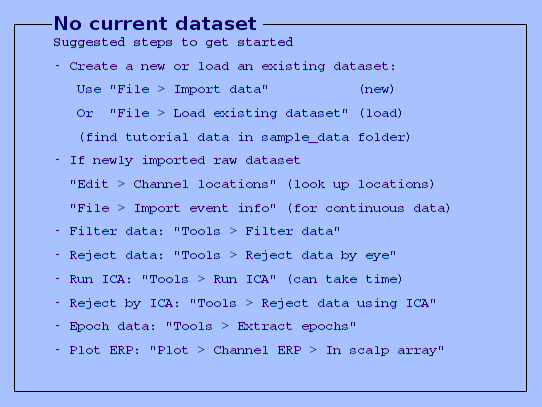

Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFMatlabIO" v3.5 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "bva-io" v1.6 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.2 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.0 (see >> help eegplugin_dipfit) - new version 3.4 available
EEGLAB: adding "firfilt" v2.1 (see >> help eegplugin_firfilt) - new version 2.4 available
EEGLAB: adding "musemonitor" v3.1 (see >> help eegplugin_musemonitor) - new version 3.2 available
You are using the latest version of EEGLAB.


eeglab;


eeglabPath = fileparts(which('eeglab')); 

[STUDY ALLEEG] = pop_loadstudy(fullfile(eeglabPath, 'sample_data/5subjects', 'n400clustedit.study'));

pop_loadset(): loading file ./s02/syn02-s253-clean.set ...
pop_loadset(): loading file ./s05/syn05-s253-clean.set ...
pop_loadset(): loading file ./s07/syn07-s253-clean.set ...
pop_loadset(): loading file ./s08/syn08-s253-clean.set ...
pop_loadset(): loading file ./s10/syn10-s253-clean.set ...
pop_loadset(): loading file ./s02/syn02-s254-clean.set ...
pop_loadset(): loading file ./s05/syn05-s254-clean.set ...
pop_loadset(): loading file ./s07/syn07-s254-clean.set ...
pop_loadset(): loading file ./s08/syn08-s254-clean.set ...
pop_loadset(): loading file ./s10/syn10-s254-clean.set ...


#### Compute ERP measure for the STUDY set. 

[STUDY ALLEEG] = std_precomp(STUDY, ALLEEG, {},'savetrials','on', ...
'interp','on',... % interpolate missing channels
'recompute','on',... % recompute measure if already present
'erp','on',... % compute ERPs
'erpparams',{'rmbase' [-300 0] }); %specify ERP baseline

Reading float file './s02/syn02-s253-clean.dat'...
Reading float file './s02/syn02-s254-clean.dat'...
Removing baseline...
Saving ERP file './s02/S02.daterp'
Reading float file './s05/syn05-s253-clean.dat'...
Reading float file './s05/syn05-s254-clean.dat'...
Removing baseline...
Saving ERP file './s05/S05.daterp'
Reading float file './s07/syn07-s253-clean.dat'...
Reading float file './s07/syn07-s254-clean.dat'...
Removing baseline...
Saving ERP file './s07/S07.daterp'
Reading float file './s08/syn08-s253-clean.dat'...
Reading float file './s08/syn08-s254-clean.dat'...
Removing baseline...
Saving ERP file './s08/S08.daterp'
Reading float file './s10/syn10-s253-clean.dat'...
Reading float file './s10/syn10-s254-clean.dat'...
Removing baseline...
Saving ERP file './s10/S10.daterp'


#### Specify statistical parameters

STUDY  = pop_statparams(STUDY,... 
'condstats','on',... % perform stats on 1st independant variable
'method','perm',... % use perumtation method
'mcorrect','fdr',...% correct for multiple comparisons using fdr
'alpha',0.01); %specify statistical threshold


### **Plot ERP time course**

We specify erpdata and erptimes to retrieve these measures from the outputs of std_erplot - lookup the help of this function for more details

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


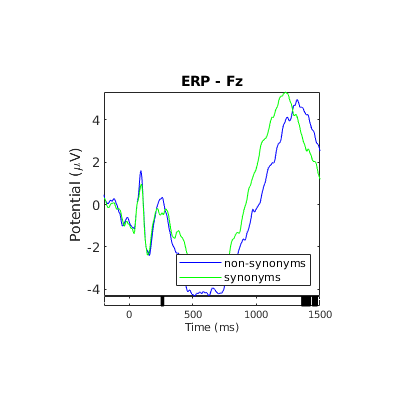

STUDY = pop_erpparams(STUDY, 'plotconditions','together'); % specify plot parameters
[STUDY erpdata erptimes] = std_erpplot(STUDY,ALLEEG,'channels',{'Fz'}, 'design', 1, 'timerange', [-200, 1500]); %select channel to plot and STUDY design

#### Plot the standard error:

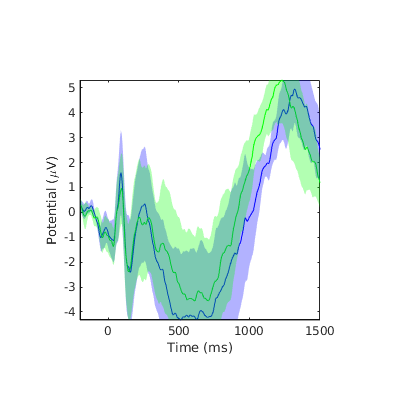

std_plotcurve(erptimes, erpdata, 'plotconditions', 'together', 'plotstderr', 'on', 'figure', 'on');

#### Plot each subject's ERP:

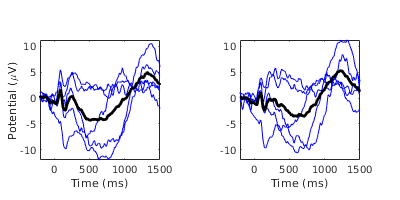

std_plotcurve(erptimes, erpdata, 'plotconditions', 'together', 'plotsubjects', 'on', 'figure', 'on');

#### **Plot the difference between two conditions**

std_plotcurve(erptimes, erpdata, 'plotdiff', 'on', 'plotconditions', 'together',  'figure', 'on');

Index exceeds array bounds.

Error in std_plotcurve (line 414)
                        opt.legend{end+1} = [ opt.legend{2} '-' opt.legend{1} ];

Plot ERP topographic map

STUDY = pop_erpparams(STUDY, 'topotime',[1200 1500] ); %specify the time range to plot the topomap
STUDY = std_erpplot(STUDY,ALLEEG,'channels',{'Fp1' 'Fpz' 'Fp2' 'AF3' 'AF4' 'F7' 'F5' 'F3' 'F1' 'Fz' 'F2' 'F4' 'F6' 'F8' 'FC5' 'FC3' 'FC1' 'FCz' 'FC2' 'FC4' 'FC6' 'T7' 'C5' 'C3' 'C1' 'Cz' 'C2' 'C4' 'C6' 'T8' 'CP1' 'CPz' 'CP2' 'CP4' 'CP6' 'TP8' 'P7' 'P5' 'P3' 'P1' 'Pz' 'P2' 'P4' 'P6' 'P8' 'PO5' 'PO3' 'PO1' 'POz' 'PO2' 'PO4' 'PO6' 'O1' 'Oz' 'O2' 'LO1' 'IO1' 'SO1' 'LO2' 'TP7' 'CP5'}, 'design', 1);